b = 50; % baseline [mm]
fLeft = 6; % focal length [mm]
fRight = 10; % focal length [mm]
ps = .006; % pixel size [mm]
xNumPix = 752; % total number of pixels in x direction of the sensor [px]
cxLeft = xNumPix/2; % left camera x center [px]
cxRight = xNumPix/2; % right camera x center [px]

camLeft = CentralCamera(...
    'focal', fLeft, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxLeft, ...
    'name', 'CameraLeft');

camRight = CentralCamera(...
    'focal', fRight, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxRight, ...
    'name', 'CameraRight');

TcamL = SE3(+0.5, 0, 0);
camLeft.T = TcamL;
TcamR = SE3(-0.5, 0, 0);
camRight.T = TcamR;

x = 1;
xLeft = zeros(2, 100); % Preallocate for left camera projections
xRight = zeros(2, 100); % Preallocate for right camera projections
for i = 0:0.1:10
    PointPos = [1, 0, i]';
    xLeft(1:2,x) = camLeft.project(PointPos);
    xRight(1:2,x) = camRight.project(PointPos);
    x = x + 1;
end

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps) % disparity [mm]

d =        NaN  120.0000   60.0000   40.0000   30.0000   24.0000   20.0000   17.1429   15.0000   13.3333   12.0000   10.9091   10.0000    9.2308    8.5714    8.0000    7.5000    7.0588    6.6667    6.3158    6.0000    5.7143    5.4545    5.2174    5.0000    4.8000    4.6154    4.4444    4.2857    4.1379    4.0000    3.8710    3.7500    3.6364    3.5294    3.4286    3.3333    3.2432    3.1579    3.0769    3.0000    2.9268    2.8571    2.7907    2.7273    2.6667    2.6087    2.5532    2.5000    2.4490
       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

ZLeft = ((b .* fLeft) ./d) .* 1000 % depth [m]

ZLeft = 1.0e+05 *

       NaN    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500    0.7750    0.8000    0.8250    0.8500    0.8750    0.9000    0.9250    0.9500    0.9750    1.0000    1.0250    1.0500    1.0750    1.1000    1.1250    1.1500    1.1750    1.2000    1.2250
       NaN       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf

ZRight = ((b .* fRight) ./d) .* 1000 % depth [m]

ZRight = 1.0e+05 *

       NaN    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500    0.2917    0.3333    0.3750    0.4167    0.4583    0.5000    0.5417    0.5833    0.6250    0.6667    0.7083    0.7500    0.7917    0.8333    0.8750    0.9167    0.9583    1.0000    1.0417    1.0833    1.1250    1.1667    1.2083    1.2500    1.2917    1.3333    1.3750    1.4167    1.4583    1.5000    1.5417    1.5833    1.6250    1.6667    1.7083    1.7500    1.7917    1.8333    1.8750    1.9167    1.9583    2.0000    2.0417
       NaN       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       In

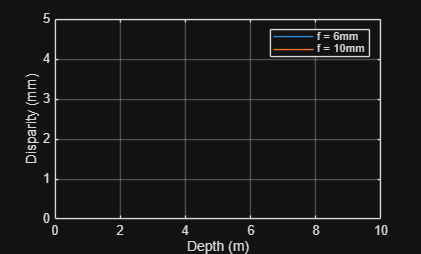



plot(d(1,:));
xlabel('Depth (m)');
ylabel('Disparity (mm)');
grid on;
hold on;
xlim([0 10]);
ylim([0 5]);
plot(ZRight(1, :));
legend('f = 6mm', 'f = 10mm');
hold off;

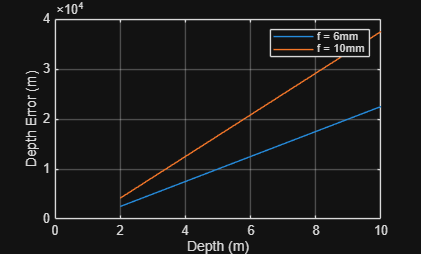


plot(ZLeft(1,:));
xlabel('Depth (m)');
ylabel('Depth Error (m)');
grid on;
hold on;
xlim([0 10]);
%ylim([-8*10^-14 10*10^-14]);
ylim("auto");
plot(ZRight(1, :));
legend('f = 6mm', 'f = 10mm');